# Spreading the Butter - Integrating the Chemical Master Equation

In this script, we will learn a bit about cytoskeletal filaments, how to write a numerical integrator in MATLAB, and the princple of the master equation.

As an example, let's think of how we can compute the probability of having a filament with a length $\ell = 3$. There are a total of four things that can happen:

- A filament of length $\ell = 2$ grows by one monomer to become $\ell = 3$.

- A filament of length $\ell = 4$ degrades by one length to become $\ell = 3$.

- A filament of length $\ell = 3$ can degrade by one to become $\ell = 2$.

- A filament of length $\ell = 3$ or  grow by one monomer to become $\ell = 4$. 

With this knowledge of how we can build a filament, we can write the complete master equation for a filament of length $\ell = 3$ a


$$P(\ell = 3, t + \Delta t) = P(\ell=3, t) + r \Delta t P(\ell=2, t) + \gamma \Delta t P(\ell = 4, t) - \Delta t P(\ell=3, t) (r + \gamma).$$


Rather than doing this by hand for all possible lengths from $\ell \in [0, \infty)$, we can write the general master equation as


$$P(\ell, t + \Delta t) = P(\ell, t) + r \Delta t P(\ell - 1, t) + \gamma \Delta t P(\ell + 1, t) - \Delta t P(\ell, t) (r + \gamma).$$


With this master equation in place, we can now figure out how the distribution changes with time! To do so, we'll use the method of [Forward-Euler integration](https://en.wikipedia.org/wiki/Euler_method).

## Forward-Euler Integration

Developing simple ways to solve ordinary differential equations has long been an area of intense research. While deriving the analytical solution may be simple in some cases, it is often useful to solve them numerically, especially if slamming out the analytical solution will give you carpal tunnel.

While there are many ways to numerically integrate these equations, in this tutorial we will examine the [Forward Euler method](https://en.wikipedia.org/wiki/Euler_method). Say we have an ordinary differential equation such as


$${dx \over dt} =  - {x \over \tau}\  ,$$


where $\tau$ is some time constant and $t$ is time. Rather than solving this analytically (although it is trivial), we can solve it numerically by starting at some given value of $x$, evaluating this equation for a given time step $\Delta t$, and updating the new value of $x$ at this new time $t + \Delta t$. WE can phrase this mathematically as 


$$x(t + \Delta t) = x(t) - {x(t) \over \tau} \Delta t .$$


Say our initial value ( $x$ at $t=0$) is $x = 10$ and $\tau = 1$. e can take a time step $\Delta t = 0.1$ and find that the change in value of $x$ is 


$$\Delta x = -{x\over \tau}\Delta t = -1.$$


WE can then compute the new value of $x$ at time $t + \Delta t$ as 


$$x(t + \Delta t) = x(t) + \Delta x = 10 - 1 = 9.$$


We can then take another step forward in time and repeat the process for as long as we would like. As the total time we'd like to integrate over becomes large, it becomes obvious why using a computer is a far more attractive approach than scribbling it by hand. 

A major point to be wary of is the instability of this method. The error in this scales with the square of our step size. We must choose a sufficiently small step in time such that at most only one computable event must occur. For example, if we are integrating exponential growth of bacterial cells, we don't want to take time steps larger than a cell division! This requirement is known as the [Courant-Friedrichs-Lewy condition](https://en.wikipedia.org/wiki/Courant%E2%80%93Friedrichs%E2%80%93Lewy_condition) and is important for many different time-marching computer simulations.

## Integrating the Chemical Master Equation

Let's write an integrator to numerically solve this master equation. We'll start by defining the chemical parameters of the system, $r$ and $\gamma$.

% Define the parameters. 
r = 9; % on rate of a monomer to the filament. Dimensions are inverse time
gamma = 10; % off rate of a monomer to the filament. Dimensions are inverse time

While the length of our cytoskeletal filament can be essentially infinite, it's not really possible for us to compute that. To get around this we can set what a "maximum length" should be in our simulation integrate over that range. You should note that this means our solution will **not** be exact, but is good enough for what we are after. For more exact numerical calculations, you should consider looking into MATLAB's standard ODE solvers. 

We will be integrating essentially over two dimensions $-$ filament length and time. This means that we will want to set up a two dimensional matrix where each column will represent a time point and each row will be an integer length of our filament. Let's go a head and define this matrix as well as the other parameters  of our system.

% Define the integration parameters. 
maxLength = 100; % The maximum length of the filament that we will integrate over. 
totalTime = 50;  % Total time of the integration in dimensions of time. 
dt = 1/ 50; % Time step for the simulation. Note that this needs to be sufficiently small!
timeSteps = totalTime / dt; % The total number of time steps we will be taking. 

% Set up the matrix in which we will store the values. 
P = zeros(maxLength, timeSteps);  % A two-dimensional matrix full of zeros. 

Before we can begin the integration, we have to set the intial condition (our matrix is full of zeros after all!). We could start our integration in any way, but for fun, let's set the intial condition for there to be zero filaments. This means we will set the first index of our matrix $P(\ell = 0, t=0) = 1.0$. 

% Set the initial condition. 
P(1, 1) = 1.0; % Remember  that MATLAB indexing begins at 1. 

Now we are finally ready to begin the integration. However, we have to be cognizant of one issue $-$ the boundary conditions. When we have $P(\ell = 0)$, for example, it doesn't make sense to have a degradation term $\gamma \Delta t P(\ell, t)$ because $0$ can't degrade! Likewise, you can't have a production term $r \Delta t P(\ell-1, t)$. When we begin our integration, we will have to compute the boundary conditions, $\ell = 0$ and $\ell =$ maxLength individually.  Let's go ahead and perform the integration. 

% Loop first through each time point. We'll start at time t=2 since we set the initial condition. 
for t=2:timeSteps
    % We'll compute the initial condition, when ell = 1, which is our first condition. 
    ell = 1;
    P(ell, t) = P(ell, t-1) + gamma * dt * P(ell + 1, t-1) - r * dt * P(ell, t - 1);
    
    % Now we can deal with the other boundary condition, when ell = maxLength. 
    ell = maxLength;
    P(ell, t) = P(ell, t-1) + r * dt * P(ell-1, t-1) - gamma * dt * P(ell, t-1);
    
    % The boundary conditions are satisfied, so we can jump ahead and go through the rest of 
    % the lengths of the filament. 
    for ell=2:(maxLength - 1) % -1 so we don't compute the final length!
        P(ell, t) = P(ell, t-1) + r * dt * P(ell-1, t-1)  + gamma * dt * P(ell+1, t-1) - ...
            dt * P(ell, t-1) * (r + gamma);
    end % This ends the length loop. 
end % This ends the time loop. 

And that's it! In just a few lines of code, we were able to integrate our master equation! Let's take a look at the distribution. Since we have three axes of information (length, time, and probability), we can plot it as a 3-D bar plot, where the height of the bars will be representative of the probability of that length, the $x$-dimension will be length, and the $y-$dimension will be time steps. Since we have so many time steps, we'll only plot every twentieth time point.

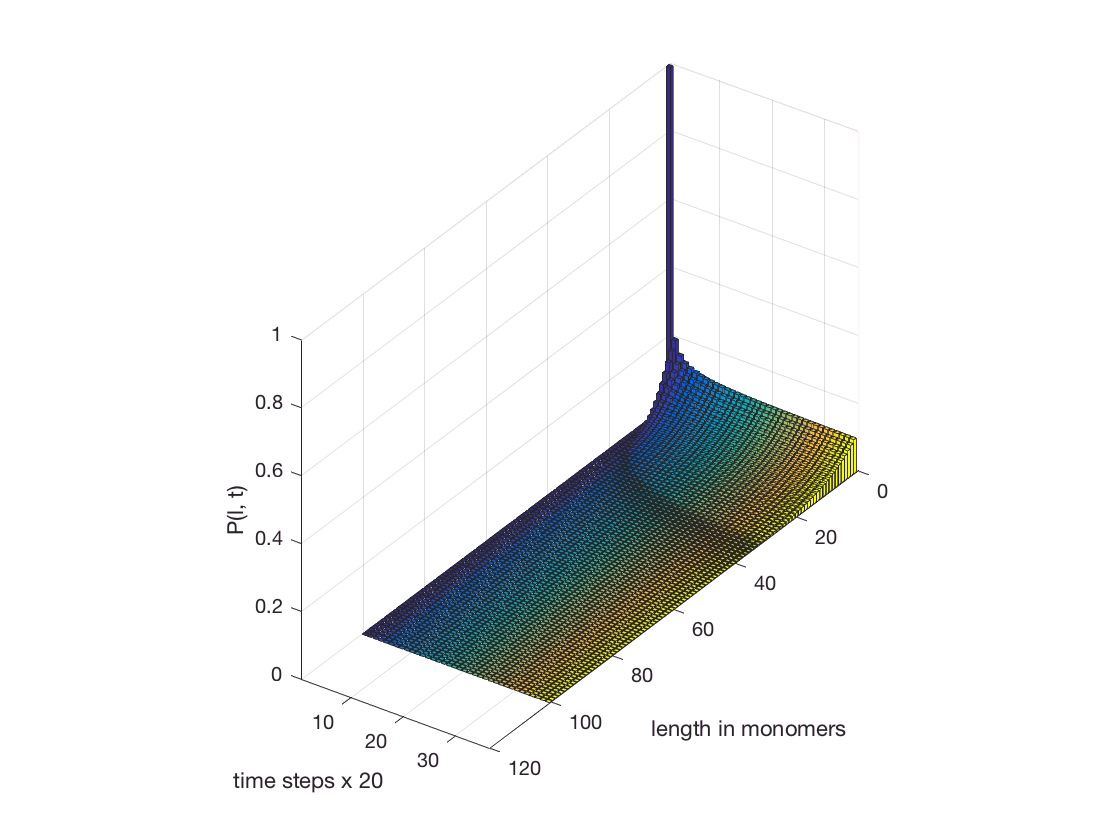

% Plot the probability vector as 3-D bar plot. 
bar3(P(:, 1:70:timeSteps)); % 1:20:timeSteps plots the first bar to the last bar taking steps of 20

% Now we just have to add labels like good scientists. 
ylabel('length in monomers')
xlabel('time steps x 20')
zlabel('P(l, t)');

As we rotate this plot around, we can see that it spreads out over time, with the mode being at 0. When we look at the end of the simulation, the distribution does look *qualitatively* exponential. Rather than saying just what it looks like, we can actually solve for this distribution analytically. 

## Solving The Distribution Analytically

Above, we wrote out the master equation that describes the length of the distribution. We can analytically solve for the steady-state distribution using 

 We can rewrite this in the form of an ordinary differential equation which summarizes the change in the probability length distribution over time, 


$${dP(\ell, t) \over dt} = r P(\ell-1) + \gamma P(\ell+1) - P(\ell)(r + \gamma).$$
 

At steady state, the change in probability for a given length $\ell$ over a time step $dt$ is $0$. By setting the above equation equal to zero, we can solve for this probability distribution,


$${dP(\ell) \over dt} = 0 = rP(\ell -1) + \gamma P(\ell + 1) + P(\ell)(r + \gamma)$$



$$\Rightarrow P(\ell)(r + \gamma) = rP(\ell - 1) + \gamma P(\ell + 1).$$
 

Now, that's not very informative of what the distribution should be. That's because it's dependent on two other lengths, $\ell + 1$ and $\ell -1$. We can use a **recursive** strategy to determine what the distribution should be dependent only on one length. A useful standard length that we can compute the distribution from is a length of $0$ (no filament at all). Let's evaluate the above expression for a length of zero,


$$r P(\ell = 0) + \overbrace{\gamma P(\ell=0)}^{\mathrm{nonsense}} = \overbrace{rP(\ell = -1)}^{\mathrm{nonsense}} + \gamma P(\ell = 1)$$
 

The two terms with the overbrace indicate terms that are non-physical (degradation from a length of zero and production from a length of -1). Now, we can rework this to determine $P(\ell)$ in terms of $P(\ell = 0)$, 


$$P(\ell = 1) = {r \over \gamma} P(\ell = 0).$$


We know know the probability of finding a filament of length $\ell = 1$ in terms of the probability of a length $\ell  = 0$ filament. Now, we can do the same procedure again for $P(\ell = 1)$, 


$$P(\ell=1)(r + \gamma) = rP(\ell=0) + \gamma P(\ell =2)$$


$\Rightarrow {r \over \gamma}P(\ell = 0) = r P(\ell = 0) + \gamma P(\ell = 2)

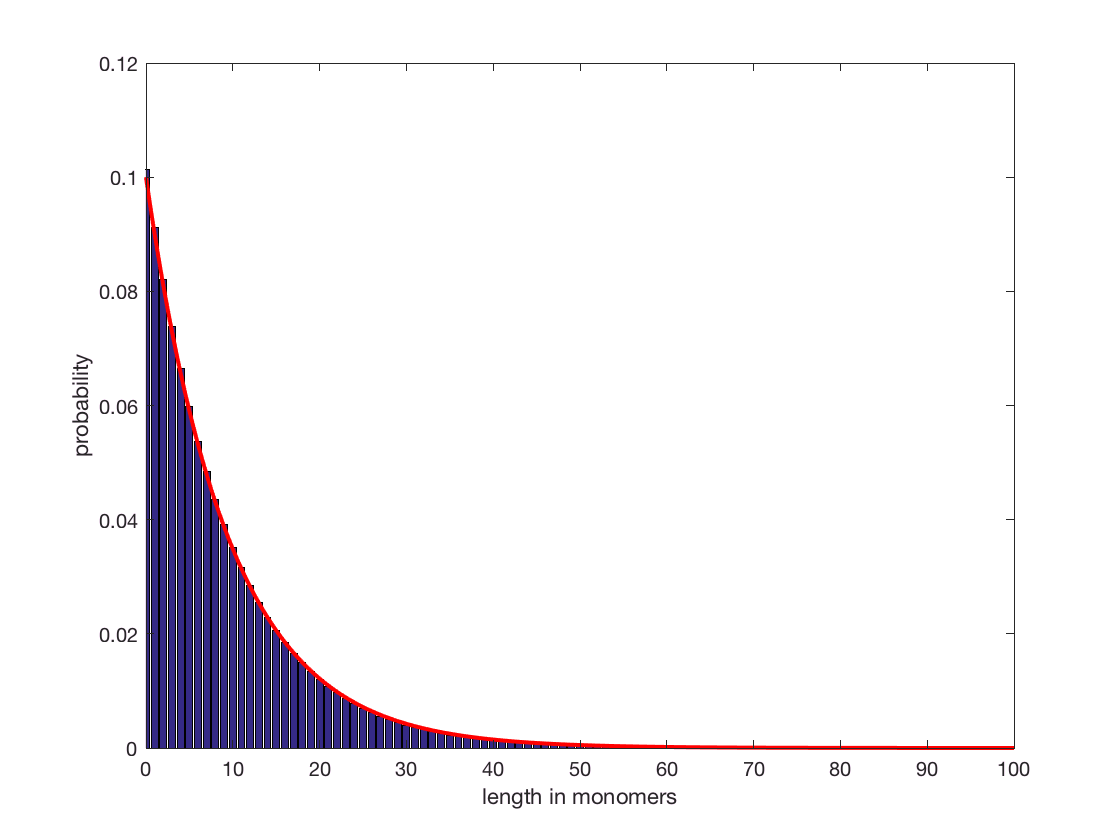

% Set up a length vector
lengths = 0:1:maxLength-1;
% Set up a more finely spaced array of points to compute the analytical solutions. 
L = linspace(0, maxLength, 1000);

% Compute the analytical solution. 
soln = (r / gamma).^L * ( 1 - (r / gamma));

% Plot the last time point of our integration and the analytical solution. 
bar(lengths, P(:, timeSteps))
hold on

% Plot the analytical solution.
plot(L, soln, 'r-', 'LineWidth', 2);

% Of course, always labels. 
xlabel('length in monomers')
ylabel('probability')

% Set the limits from 0 to maxLength -1
xlim([0, maxLength])
hold off